# **Visión Artificial. GIEC.**

# **	Sistemas de Visión Artificial. GIC.**

**	Miguel Ángel García, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Autor(es):**

**Fecha:**

El objetivo principal de esta práctica es familiarizarse con los principales operadores morfológicos y analizar el efecto que producen el **tipo, la forma y el tamaño del elemento estructurante** sobre distintos tipos de imágenes.

close all
clear all

1) Lea la imagen en color 'autumn.tif' y muéstrela.

2) Utilizando la función strel, cree un elemento estructurante con forma de disco de 5 píxeles de radio. 

3) Erosione y dilate la imagen utilizando dicho elemento estructurante y muestre conjuntamente la imagen original y las dos imágenes resultantes. Tenga en cuenta que, en una imagen RGB, MATLAB aplica estas operaciones de forma independiente a cada una de las tres componentes de color.

Además, se pide: 

- Ejecute el programa cargando la imagen en escala de grises `'rice.png' `y  la imagen binaria `'circles.png'`. Observe el comportamiento de los operadores morfológicos sobre los distintos tipos de imágenes.¿Qué diferencias ve?

- Elementos estructurantes. Observe el efecto de las operaciones morfológicas utilizadas en (3) con elementos estructurantes de diferentes formas y tamaños (ver ayuda: [https://es.mathworks.com/help/images/ref/strel.html?s_tid=doc_ta).](https://es.mathworks.com/help/images/ref/strel.html?s_tid=doc_ta).)

- Operadores morfológicos. Cargue la imagen en escala de grises `'rice.png' `y realice una operación de umbralizado con la función `imbinarize`, que por defecto utiliza el método de Otsu. Utilice las funciones `imclose` o `imopen` para eliminar los pequeños píxeles aislados que puedan estar en el fondo de la imagen. Tenga en cuenta que el tipo y tamaño del elemento estructurante debe ser ajustado.

- Repita la pregunta anterior pero utilizando la imagen original complementada (utilice la función `imcomplement`).

- Comente las diferencias en el efecto sobre los detalles en la imagen original y en la complementada.

Dada la imagen "HuellaOrig.jpg", que presenta ruido (tanto puntos negros dentro de la huella, como puntos blancos por fuera), se pide:

- Crear una imagen en la que se hayan eliminado los puntos blancos de ruido,

- A partir de dicha imagen, eliminar también los puntos negros dentro de la huella, para generar una imagen limpia. 

- Elegir y justificar el tipo y tamaño del elemento estructurante y las operaciones morfológicas utilizadas.

- Mostrar conjuntamente:

- imagen original; 

- resultado después de eliminar los puntos blancos; 

- resultado final después de eliminar también los puntos negros.

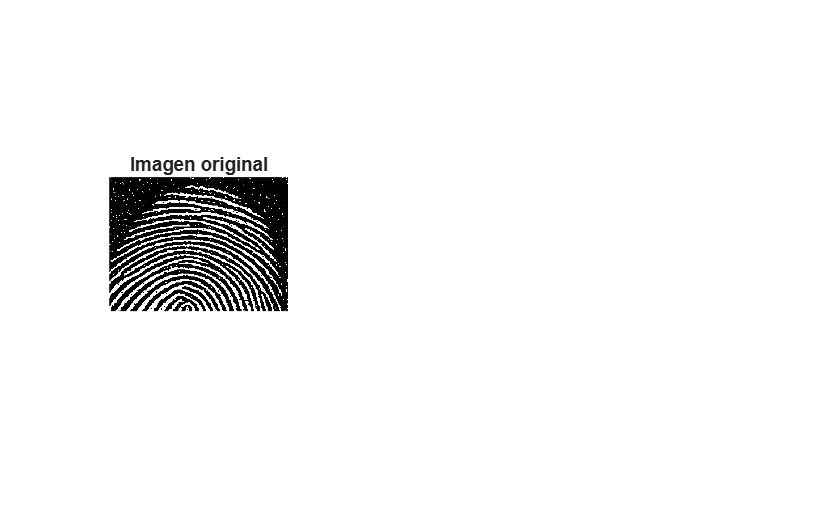

clear all
close all
se = strel('disk', 4);
original = imread('HuellaOrig.jpg');
figure;
subplot(1,3,1)
imshow(original);
title('Imagen original');

Dado el siguiente código:

% close all
% clear all

Step 1) Reading the Image

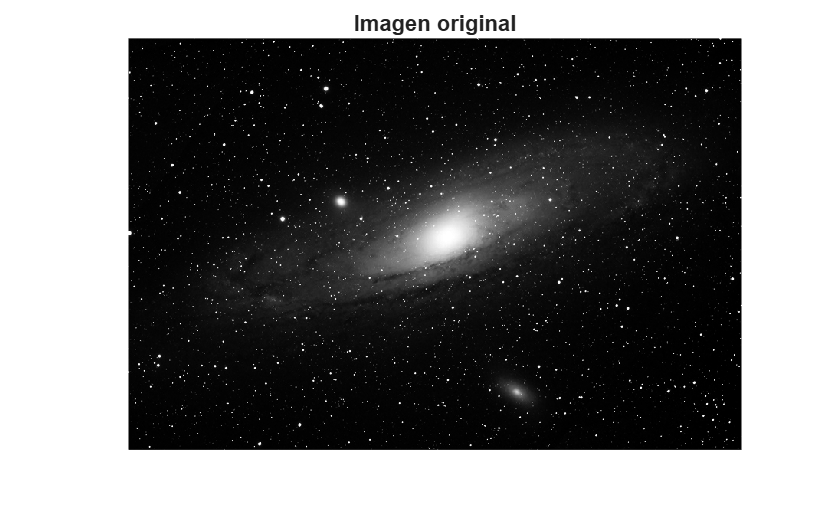

original = imread('galaxy.png');
figure;
imshow(original);
title('Imagen original');

Step 2) Creating a structuring element.

se = strel('disk',50);

Step 3) Top or Bottom Hat.

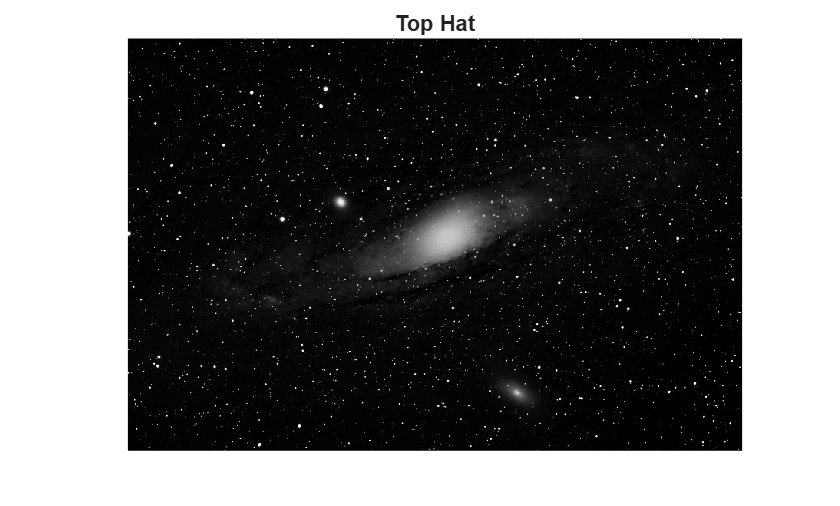

tophat = imtophat(original,se);
figure;
imshow(tophat);
title('Top Hat');

Se pide: 

- Suponga que solo interesan las estrellas pequeñas y que se desea eliminar la contribución de la galaxia. Las estrellas presentan tamaños del orden de unos pocos píxeles (aproximadamente 2–6 píxeles de radio), mientras que la galaxia presenta dimensiones muy superiores. Pruebe distintos radios para un elemento estructurante en forma de disco y determine experimentalmente un tamaño que permita conservar las estrellas pequeñas y eliminar la galaxia.

- Cuando el fondo es blanco y el primer plano es oscuro, debemos cambiar el enfoque. Obtenga la imagen complementada con la función `imcomplement. `Aplique sobre ella la transformación *white top-hat* utilizada anteriormente y observe el resultado. ¿Por qué deja de ser adecuada esta operación para extraer las estrellas? Determine qué operación morfológica resulta ahora apropiada para extraer estructuras pequeñas más oscuras que su entorno, aplíquela y muestre el resultado.